LPV-RTAC class2

clear;
w_max = 0.6817;
w_min = 0;
alpha1 = 0;
alpha2 = alpha1;
beta1 = 0.6817;
beta2 = 0.3183;
eta1 = -0.6817;
nu1 = 0.6817;
eta2 = -0.6817;
nu2 = 0.6817;
eps_p = 0.2;
A0 = [0,1,0,0;
    -1,0,eps_p/pi,0;
    0,0,0,1;
    0,0,0,0];
B0 = [0,0,0,1]';
A1 = [0,0,0,0;
    0,0,eps_p,0;
    0,0,0,0;
    0,0,0,0];
B1 = zeros(4,1);
A2 = -A1;
B2 = B1;

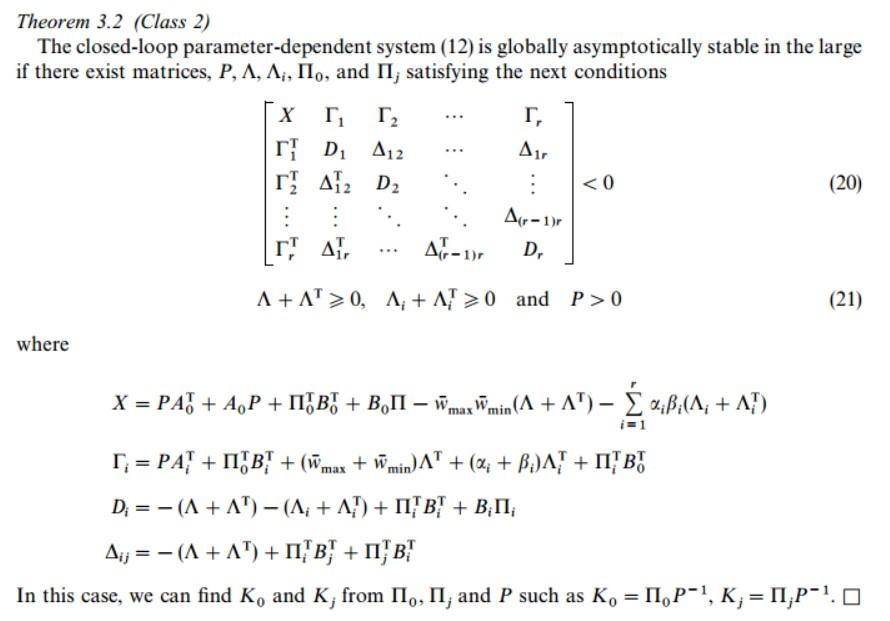

pvar z1 z2 z3 z4;
z=[z1;z2;z3;z4];
prog = sosprogram(z);
% [prog,P] = sospolymatrixvar(prog,monomials(z,0),[4,4],'symmetric');
[prog,P] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Pi0] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Pi1] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Pi2] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Lamda] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Lamda1] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Lamda2] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
X = P*A0'+A0*P+Pi0'*B0'+B0*Pi0-w_max*w_min*(Lamda+Lamda')...
    -alpha1*beta1*(Lamda1+Lamda1')-alpha2*beta2*(Lamda2+Lamda2');
Tao1 = P*A1'+Pi0'*B1'+(w_max+w_min)*Lamda'+(alpha1+beta1)*Lamda1'+Pi1'*B0';
Tao2 = P*A2'+Pi0'*B2'+(w_max+w_min)*Lamda'+(alpha2+beta2)*Lamda2'+Pi2'*B0';
D1 = -(Lamda+Lamda')-(Lamda1+Lamda1')+Pi1'*B1'+B1*Pi1;
D2 = -(Lamda+Lamda')-(Lamda2+Lamda2')+Pi2'*B2'+B2*Pi2;
Delta12 = -(Lamda+Lamda')+Pi1'*B2'+Pi2'*B1';
% F = [X,Tao1,Tao2;
%     Tao1',D1,Delta12;
%     Tao2',Delta12',D2];
% %添加约束
% % prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
% prog = sosmatrixineq(prog, -F-(1e-8), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda+Lamda'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda1+Lamda1'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda2+Lamda2'), 'quadraticMineq');
% prog = sosmatrixineq(prog, P-(1e-5), 'quadraticMineq');
% %求解
% prog = sossolve(prog);
% %返回值
% P = double(sosgetsol(prog,P));
% Pi0 = double(sosgetsol(prog,Pi0));
% Pi1 = double(sosgetsol(prog,Pi1));
% Pi2 = double(sosgetsol(prog,Pi2));
% %状态反馈增益阵
% K0 = Pi0/P
% K1 = Pi1/P
% K2 = Pi2/P

保性能控制器

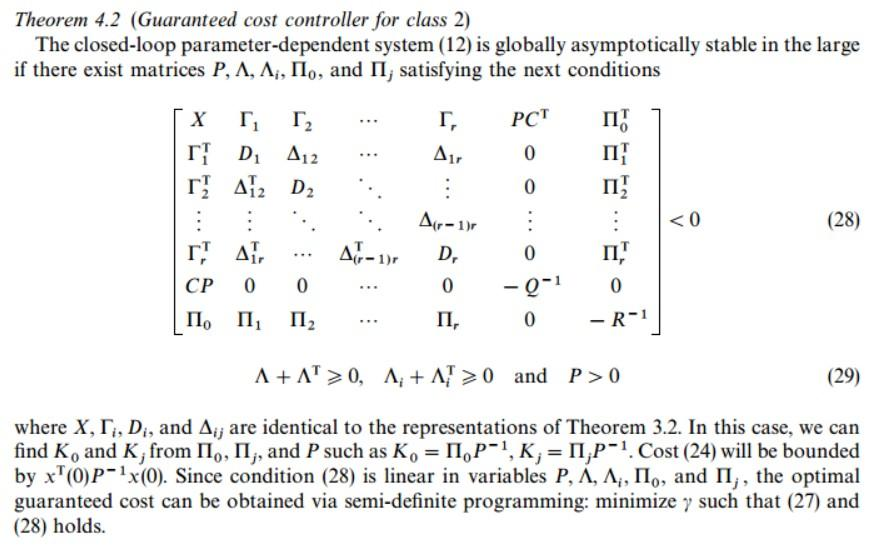

[prog,gamma] = sospolymatrixvar(prog,monomials(z,0),[1,1]);
C = [1,0,1,0];
Q = 1;
R = 1;
F1 = [X,   Tao1,        Tao2,   P*C',            Pi0';
    Tao1',  D1,        Delta12,   zeros(4,1),    Pi1';
    Tao2', Delta12',       D2,    zeros(4,1),    Pi2';
     C*P,zeros(1,4), zeros(1,4),    -Q,           0;
     Pi0,   Pi1,         Pi2,       0,           -R];
x0 = [0,0,0,0]';
M = [gamma,x0';
    x0,P];
%添加约束
% prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
prog = sosmatrixineq(prog, -F1-(1e-8), 'quadraticMineq');
prog = sosmatrixineq(prog, M, 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda+Lamda'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda1+Lamda1'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda2+Lamda2'), 'quadraticMineq');
prog = sosmatrixineq(prog, P-(1e-5), 'quadraticMineq');
%设置目标问题min
prog = sossetobj(prog, gamma);
%求解
prog = sossolve(prog);

Size: 362  160
 
SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Put 77 free variables in a quadratic cone
eqs m = 160, order n = 38, dim = 364, blocks = 8
nnz(A) = 471 + 0, nnz(ADA) = 23318, nnz(L) = 11739
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.13E-01 0.000
  1 :  -2.40E-01 1.42E-01 0.000 0.2771 0.9000 0.9000   1.77  1  1  1.8E+00
  2 :  -1.17E-01 5.56E-02 0.000 0.3915 0.9000 0.9000   1.85  1  1  6.6E-01
  3 :  -2.95E-02 1.57E-02 0.000 0.2819 0.9000 0.9000   1.54  1  1  3.7E-01
  4 :  -8.65E-03 4.27E-03 0.000 0.2725 0.9000 0.9000   1.41  1  1  2.4E-01
  5 :  -2.47E-03 1.36E-03 0.000 0.3178 0.9000 0.9000   1.64  1  1  1.6E-01
  6 :  -4.54E-04 3.28E-04 0.000 0.2413 0.9000 0.9000   1.76  1  1  4.8E-02
  7 :  -1.26E-05 1.11E-05 0.000 0.0338 0.9900 0.9900   1.33  1  1  1.1E-03
  8 :  -1.32E-09 1.16E-09 0.000 0.0001 1.0000 1.0000   1.01  1  1  1.

%返回值
P = double(sosgetsol(prog,P));
Pi0 = double(sosgetsol(prog,Pi0));
Pi1 = double(sosgetsol(prog,Pi1));
Pi2 = double(sosgetsol(prog,Pi2));
%状态反馈增益阵
K0 = Pi0/P

K0 =    -1.7428   -6.3886   -3.5574   -0.7360


K1 = Pi1/P

K1 =    -0.1507   -0.2781   -0.6067   -0.3451


K2 = Pi2/P

K2 =    -0.2417   -2.1851   -0.5800   -0.2451
